kappa  = 9.766785;   
theta  = 0.033274;   
xi     = 1.921424;   
rho    = -0.746108;   
v0     = 0.007872;       % variance initiale (GJR annualisé)
S0     = 44.29;          % spot ZCN au 2 avril 2026
r      = 0.0253;     
q      = 0.02143814;     



rng(12345, 'twister');   

T   = 1;         % maturité (1 an)
M   = 12;        % mensuelles
N   = 500000;     
n   = 252;       
dt  = T / n;     
N0  = 1000;      % nominal

temps_obs = round((1:M) / M * n);   
Delta     = 1 / M;                  

% Facteurs d'actualisation mensuels
t_mois      = (1:M)' / M;
disc_factor = exp(-r * t_mois);



[S_Q, ~, RV_Q] = simulate_heston_Q(S0, v0, kappa, theta, xi, rho, r, q, dt, n, N, temps_obs);


idx_dates = [0, temps_obs];   % indices : 0, t1, t2, ..., t12
R_Q = zeros(M, N);
for k = 1:M
    S_prev = S_Q(idx_dates(k)   + 1, :);
    S_curr = S_Q(idx_dates(k+1) + 1, :);
    R_Q(k,:) = (S_curr - S_prev) ./ S_prev;
end




## Configuration 1 : Conservatrice

c0_1      = 0.02;   % coupon plancher annualisé
alpha_p_1 = 0.010;    % participation en régime normal
b_1       = 0.05;    % seuil de déclenchement du régime baissier 

alpha_m_1 = solve_fair_alpha_minus(RV_Q, R_Q, c0_1, alpha_p_1, b_1, M, disc_factor, N0, r, T);
fprintf('alpha^- equitable = %.4f\n', alpha_m_1);

alpha^- equitable = 0.0959


V0_1 = price_product_Q(RV_Q, R_Q, c0_1, alpha_m_1, alpha_p_1, b_1, M, disc_factor, N0, r, T);
fprintf('V0 verif          = %.4f  (N0 = %d)\n', V0_1, N0);

V0 verif          = 1000.0000  (N0 = 1000)


## Configuration 2 : Dynamique

c0_2      = 0.009;   
alpha_p_2 = 0.01;    
b_2       = 0.05;    

alpha_m_2 = solve_fair_alpha_minus(RV_Q, R_Q, c0_2, alpha_p_2, b_2, M, disc_factor, N0, r, T);

fprintf('alpha^- equitable = %.4f\n', alpha_m_2);

alpha^- equitable = 0.3552



V0_2 = price_product_Q(RV_Q, R_Q, c0_2, alpha_m_2, alpha_p_2, b_2, M, disc_factor, N0, r, T);
fprintf('V0 verif          = %.4f  (N0 = %d)\n', V0_2, N0);

V0 verif          = 1000.0000  (N0 = 1000)


% distrib des coupons sous Q


[C1_Q, ~] = compute_coupons(RV_Q, R_Q, c0_1, alpha_m_1, alpha_p_1, b_1, M);
[C2_Q, ~] = compute_coupons(RV_Q, R_Q, c0_2, alpha_m_2, alpha_p_2, b_2, M);


fprintf('  Quantiles [10%% 50%% 90%%] : '); disp(quantile(C1_Q(:), [0.10 0.50 0.90]));

  Quantiles [10% 50% 90%] :     0.0206    0.0213    0.0395



fprintf('  Moyenne                  : %.6f\n', mean(C1_Q(:)));

  Moyenne                  : 0.025330


fprintf('  Ecart-type               : %.6f\n', std(C1_Q(:)));

  Ecart-type               : 0.011644


fprintf('  Quantiles [10%% 50%% 90%%] : '); disp(quantile(C2_Q(:), [0.10 0.50 0.90]));

  Quantiles [10% 50% 90%] :     0.0096    0.0103    0.0812



fprintf('  Moyenne                  : %.6f\n', mean(C2_Q(:)));

  Moyenne                  : 0.025338


fprintf('  Ecart-type               : %.6f\n', std(C2_Q(:)));

  Ecart-type               : 0.044140


## Analyse de sensibilite

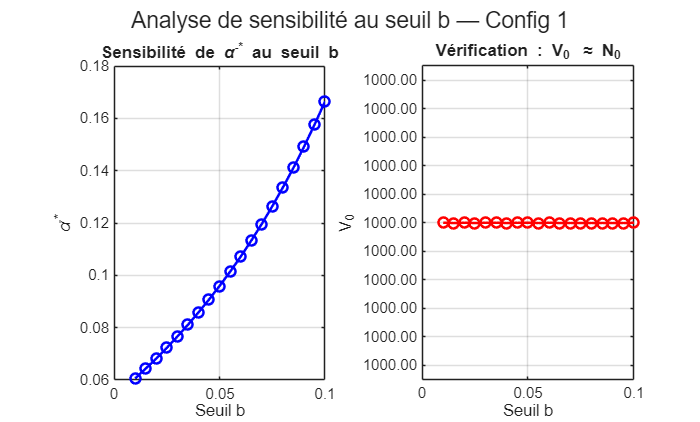

% Impact de b sur alpha^- equitable (Config 1) 

b_range = 0.01 : 0.005 : 0.10;
alpha_m_b1  = zeros(size(b_range));
V0_b1       = zeros(size(b_range));

for i = 1:length(b_range)
    b_i = b_range(i);
    am  = solve_fair_alpha_minus(RV_Q, R_Q, c0_1, alpha_p_1, b_i, M, disc_factor, N0, r, T);
    alpha_m_b1(i) = am;
    if isnan(am)
        V0_b1(i) = NaN;
    else
        V0_b1(i) = price_product_Q(RV_Q, R_Q, c0_1, am, alpha_p_1, b_i, M, disc_factor, N0, r, T);
    end
end

figure;
subplot(1,2,1);
plot(b_range, alpha_m_b1, 'b-o', 'LineWidth', 1.5);
xlabel('Seuil b'); ylabel('\alpha^{-*}');
title('Sensibilité de \alpha^{-*} au seuil b');
grid on;

subplot(1,2,2);
plot(b_range, V0_b1, 'r-o', 'LineWidth', 1.5);
xlabel('Seuil b'); ylabel('V_0');
title('Vérification : V_0 \approx N_0');
grid on;
ytickformat('%.2f') 
sgtitle('Analyse de sensibilité au seuil b — Config 1');

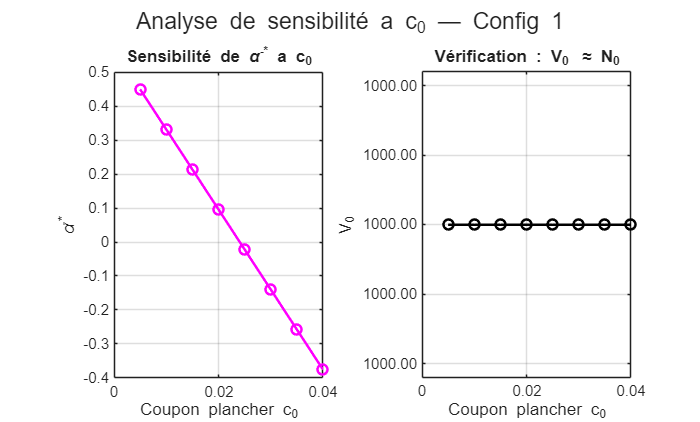

% Impact de c0 sur alpha^- equitable (Config 1) 

c0_range_1 = 0.005 : 0.005 : 0.040;
alpha_m_c1 = zeros(size(c0_range_1));
V0_c1      = zeros(size(c0_range_1));

for i = 1:length(c0_range_1)
    c0_i = c0_range_1(i);
    am   = solve_fair_alpha_minus(RV_Q, R_Q, c0_i, alpha_p_1, b_1, M, disc_factor, N0, r, T);
    alpha_m_c1(i) = am;
    if isnan(am)
        V0_c1(i) = NaN;
    else
        V0_c1(i) = price_product_Q(RV_Q, R_Q, c0_i, am, alpha_p_1, b_1, M, disc_factor, N0, r, T);
    end
end

figure;
subplot(1,2,1);
plot(c0_range_1, alpha_m_c1, 'm-o', 'LineWidth', 1.5);
xlabel('Coupon plancher c_0'); ylabel('\alpha^{-*}');
title('Sensibilité de \alpha^{-*} a c_0');
grid on;

subplot(1,2,2);
plot(c0_range_1, V0_c1, 'k-o', 'LineWidth', 1.5);
xlabel('Coupon plancher c_0'); ylabel('V_0');
title('Vérification : V_0 \approx N_0');
grid on;
ytickformat('%.2f')
sgtitle('Analyse de sensibilité a c_0 — Config 1');

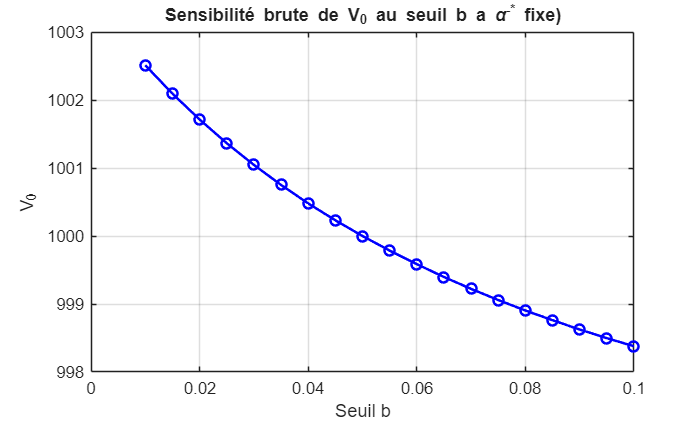


% Sensibilité brute : impact de b sur V0 (alpha^- fixé, Config 1) -

b_range_brut = 0.01 : 0.005 : 0.10;
V0_b1_brut   = zeros(size(b_range_brut));

for i = 1:length(b_range_brut)
    b_i = b_range_brut(i);
    V0_b1_brut(i) = price_product_Q(RV_Q, R_Q, c0_1, alpha_m_1, alpha_p_1, b_i, M, disc_factor, N0, r, T);
end

figure;
plot(b_range_brut, V0_b1_brut, 'b-o', 'LineWidth', 1.5);
xlabel('Seuil b'); ylabel('V_0');
title('Sensibilité brute de V_0 au seuil b a \alpha^{-*} fixe)');
grid on;

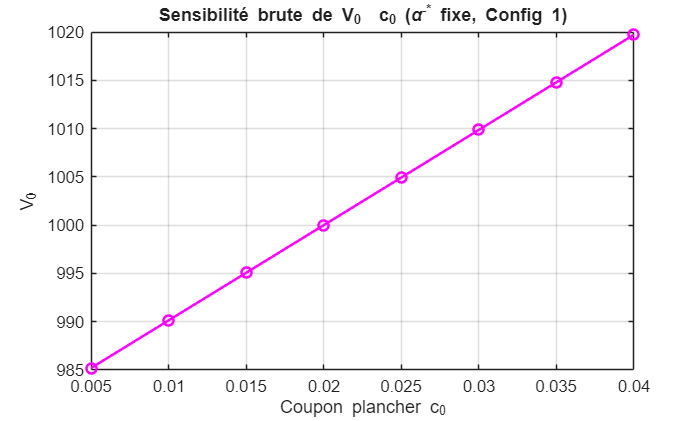


% Sensibilité brute : impact de c0 sur V0 (alpha^- fixé, Config 1) 

c0_range_brut_1 = 0.005 : 0.005 : 0.040;
V0_c1_brut      = zeros(size(c0_range_brut_1));

for i = 1:length(c0_range_brut_1)
    c0_i = c0_range_brut_1(i);
    V0_c1_brut(i) = price_product_Q(RV_Q, R_Q, c0_i, alpha_m_1, alpha_p_1, b_1, M, disc_factor, N0, r, T);
end

figure;
plot(c0_range_brut_1, V0_c1_brut, 'm-o', 'LineWidth', 1.5);
xlabel('Coupon plancher c_0'); ylabel('V_0');
title('Sensibilité brute de V_0  c_0 (\alpha^{-*} fixe, Config 1)');
grid on;

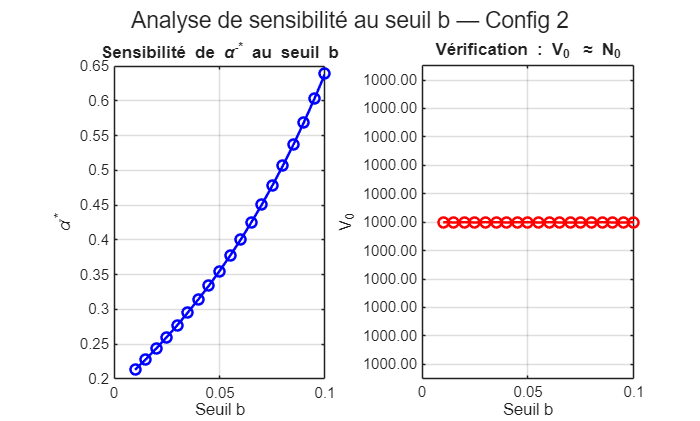

% Impact de b sur alpha^- equitable (Config 2)

alpha_m_b2  = zeros(size(b_range));
V0_b2       = zeros(size(b_range));

for i = 1:length(b_range)
    b_i = b_range(i);
    am  = solve_fair_alpha_minus(RV_Q, R_Q, c0_2, alpha_p_2, b_i, M, disc_factor, N0, r, T);
    alpha_m_b2(i) = am;
    if isnan(am)
        V0_b2(i) = NaN;
    else
        V0_b2(i) = price_product_Q(RV_Q, R_Q, c0_2, am, alpha_p_2, b_i, M, disc_factor, N0, r, T);
    end
end

figure;
subplot(1,2,1);
plot(b_range, alpha_m_b2, 'b-o', 'LineWidth', 1.5);
xlabel('Seuil b'); ylabel('\alpha^{-*}');
title('Sensibilité de \alpha^{-*} au seuil b');
grid on;

subplot(1,2,2);
plot(b_range, V0_b2, 'r-o', 'LineWidth', 1.5);
xlabel('Seuil b'); ylabel('V_0');
title('Vérification : V_0 \approx N_0');
grid on;
ytickformat('%.2f')
sgtitle('Analyse de sensibilité au seuil b — Config 2');

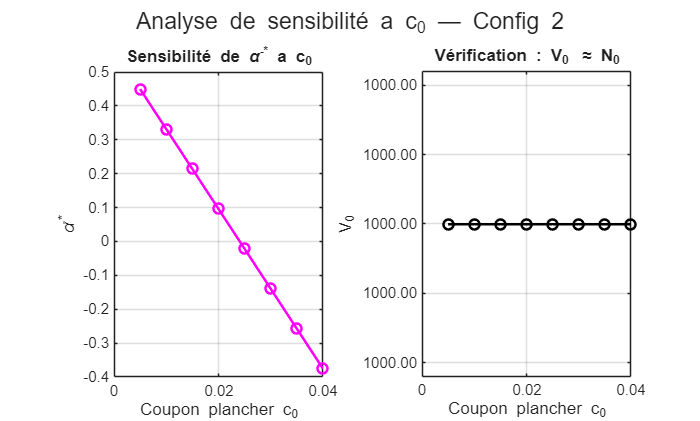

%  Impact de c0 sur alpha^- equitable (Config 2) 

c0_range_2 = 0.005 : 0.005 : 0.040;
alpha_m_c2 = zeros(size(c0_range_2));
V0_c2      = zeros(size(c0_range_2));

for i = 1:length(c0_range_2)
    c0_i = c0_range_2(i);
    am   = solve_fair_alpha_minus(RV_Q, R_Q, c0_i, alpha_p_2, b_2, M, disc_factor, N0, r, T);
    alpha_m_c2(i) = am;
    if isnan(am)
        V0_c2(i) = NaN;
    else
        V0_c2(i) = price_product_Q(RV_Q, R_Q, c0_i, am, alpha_p_2, b_2, M, disc_factor, N0, r, T);
    end
end

figure;
subplot(1,2,1);
plot(c0_range_2, alpha_m_c2, 'm-o', 'LineWidth', 1.5);
xlabel('Coupon plancher c_0'); ylabel('\alpha^{-*}');
title('Sensibilité de \alpha^{-*} a c_0');
grid on;

subplot(1,2,2);
plot(c0_range_2, V0_c2, 'k-o', 'LineWidth', 1.5);
xlabel('Coupon plancher c_0'); ylabel('V_0');
title('Vérification : V_0 \approx N_0');
grid on;
ytickformat('%.2f')
sgtitle('Analyse de sensibilité a c_0 — Config 2');

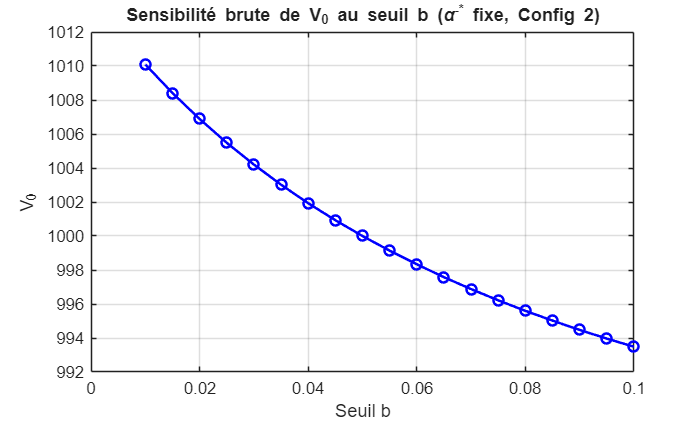

%  Sensibilité brute : impact de b sur V0 (alpha^- fixé, Config 2) 

b_range_brut2 = 0.01 : 0.005 : 0.10;
V0_b2_brut    = zeros(size(b_range_brut2));

for i = 1:length(b_range_brut2)
    b_i = b_range_brut2(i);
    V0_b2_brut(i) = price_product_Q(RV_Q, R_Q, c0_2, alpha_m_2, alpha_p_2, b_i, M, disc_factor, N0, r, T);
end

figure;
plot(b_range_brut2, V0_b2_brut, 'b-o', 'LineWidth', 1.5);
xlabel('Seuil b'); ylabel('V_0');
title('Sensibilité brute de V_0 au seuil b (\alpha^{-*} fixe, Config 2)');
grid on;

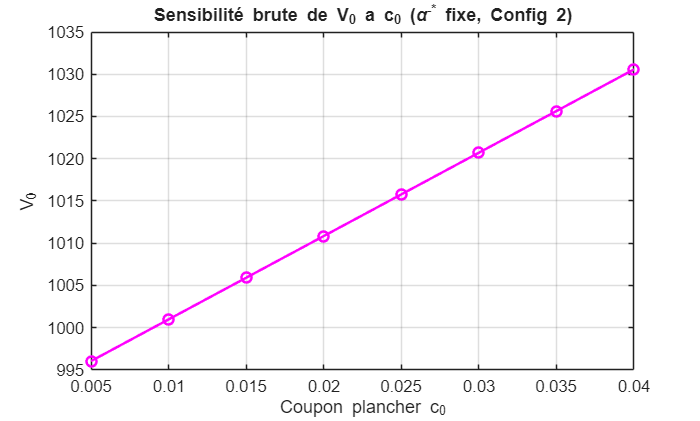

% Sensibilité brute : impact de c0 sur V0 (alpha^- fixé, Config 2) 

c0_range_brut_2 = 0.005 : 0.005 : 0.040;
V0_c2_brut      = zeros(size(c0_range_brut_2));

for i = 1:length(c0_range_brut_2)
    c0_i = c0_range_brut_2(i);
    V0_c2_brut(i) = price_product_Q(RV_Q, R_Q, c0_i, alpha_m_2, alpha_p_2, b_2, M, disc_factor, N0, r, T);
end

figure;
plot(c0_range_brut_2, V0_c2_brut, 'm-o', 'LineWidth', 1.5);
xlabel('Coupon plancher c_0'); ylabel('V_0');
title('Sensibilité brute de V_0 a c_0 (\alpha^{-*} fixe, Config 2)');
grid on;


function [S, V, RV] = simulate_heston_Q(S0, v0, kappa, theta, xi, rho, r, q, dt, n, N, temps_obs)

    M = length(temps_obs);

    S = zeros(n+1, N);
    V = zeros(n+1, N);

    S(1,:) = S0;
    V(1,:) = v0;

    % Décomposition de Cholesky pour la corrélation rho
    L = [1, 0; rho, sqrt(1 - rho^2)];

    for t = 1:n
        Z      = randn(2, N);
        Z_corr = L * Z;

        dWs = sqrt(dt) * Z_corr(1,:);
        dWv = sqrt(dt) * Z_corr(2,:);

        % Troncature : max(V, 0) pour éviter les variances négatives
        Vt = max(V(t,:), 0);

        V(t+1,:) = max(V(t,:) + kappa*(theta - Vt)*dt + xi*sqrt(Vt).*dWv, 0);
        S(t+1,:) = S(t,:) .* exp((r - q - 0.5*Vt)*dt + sqrt(Vt).*dWs);
    end

    
    Rets = log(S(2:end,:) ./ S(1:end-1,:));

    
    RV       = zeros(M, N);
    idx_prev = 0;

    for k = 1:M
        idx_k  = temps_obs(k);
        rets_k = Rets(idx_prev+1:idx_k, :);
        nk     = size(rets_k, 1);
        RV(k,:) = sqrt(252 / nk * sum(rets_k.^2, 1));
        idx_prev = idx_k;
    end
end



function [coupons, alpha_k] = compute_coupons(RV, R, c0, alpha_minus, alpha_plus, b, M)


    % Indicatrice de régime baissier 
    regime_baissier = (R <= -b);

    % Participation effective : alpha_minus ou alpha_plus selon le régime
    alpha_k = alpha_plus * ones(M, size(R,2));
    alpha_k(regime_baissier) = alpha_minus;

    % Coupon annualisé
    coupons = c0 + alpha_k .* RV;
end



function V0 = price_product_Q(RV, R, c0, alpha_minus, alpha_plus, b, M, disc_factor, N0, r, T)


    Delta = 1 / M;

    [coupons, ~] = compute_coupons(RV, R, c0, alpha_minus, alpha_plus, b, M);

    coupon_leg_PV = N0 * Delta * sum(disc_factor .* mean(coupons, 2));
    capital_PV    = exp(-r * T) * N0;

    V0 = capital_PV + coupon_leg_PV;
end



function alpha_m_star = solve_fair_alpha_minus(RV, R, c0, alpha_plus, b, M, disc_factor, N0, r, T)

%  alpha^- = (N0 - terme_fixe) / terme_variable

    Delta = 1 / M;

    % Indicatrice régime baissier
    regime_baissier = (R <= -b);    
    regime_normal   = ~regime_baissier;

    % Espérances empiriques par période
    E_RV_moins = mean(RV .* regime_baissier, 2);  
    E_RV_plus  = mean(RV .* regime_normal,   2);   

    % Terme fixe : capital + coupon plancher + participation normale
    terme_fixe = exp(-r * T) * N0 ...
                 + N0 * Delta * sum(disc_factor * c0) ...
                 + N0 * Delta * sum(disc_factor .* alpha_plus .* E_RV_plus);

    % Terme variable : contribution de alpha^-
    terme_var = N0 * Delta * sum(disc_factor .* E_RV_moins);

    if abs(terme_var) < 1e-12
        warning('solve_fair_alpha_minus : terme variable nul, alpha^- non défini.');
        alpha_m_star = NaN;
    else
        alpha_m_star = (N0 - terme_fixe) / terme_var;
    end
end


## Simulation sous P


mu_P    = 0.1108;      % rendement moyen annualise historique
kappa_P = 27.900162;
theta_P = 0.017771;
xi_P    = 0.550470;
rho_P   = -0.746108;

rng(12345, 'twister');

[S_P, V_P, RV_P] = simulate_heston_P(S0, v0, kappa_P, theta_P, xi_P, rho_P, ...
                                     mu_P, dt, n, N, temps_obs);

% Rendements mensuels sous P
idx_dates = [0, temps_obs];

R_P = zeros(M, N);
for k = 1:M
    S_prev = S_P(idx_dates(k)   + 1, :);
    S_curr = S_P(idx_dates(k+1) + 1, :);
    R_P(k,:) = (S_curr - S_prev) ./ S_prev;
end

%% Coupons sous P avec les parametres calibres sous Q

[C1_P, alpha1_P] = compute_coupons(RV_P, R_P, c0_1, alpha_m_1, alpha_p_1, b_1, M);
[C2_P, alpha2_P] = compute_coupons(RV_P, R_P, c0_2, alpha_m_2, alpha_p_2, b_2, M);

coupon_total_1_P = N0 * Delta * sum(C1_P, 1);
coupon_total_2_P = N0 * Delta * sum(C2_P, 1);

CF_total_1_P = N0 + coupon_total_1_P;
CF_total_2_P = N0 + coupon_total_2_P;

%% Rendement total sur un an par rapport au nominal

rendement_1_P = (CF_total_1_P - N0) / N0 * 100;
rendement_2_P = (CF_total_2_P - N0) / N0 * 100;

fprintf('  Moyenne rendement  (Conf 1)     : %.4f%%\n', mean(rendement_1_P));

  Moyenne rendement  (Conf 1)     : 2.2313%


fprintf('  Ecart-type rendement    : %.4f%%\n', std(rendement_1_P));

  Ecart-type rendement    : 0.1205%


fprintf('  Minimum                 : %.4f%%\n', min(rendement_1_P));

  Minimum                 : 2.0874%


fprintf('  Maximum                 : %.4f%%\n', max(rendement_1_P));

  Maximum                 : 3.2356%


fprintf('  Quantiles [5%% 10%% 50%% 90%% 95%%] :\n');

  Quantiles [5% 10% 50% 90% 95%] :


disp(quantile(rendement_1_P, [0.05 0.10 0.50 0.90 0.95]));

    2.1127    2.1167    2.2248    2.3971    2.4629



fprintf('  Moyenne rendement  (Conf 2)     : %.4f%%\n', mean(rendement_2_P));

  Moyenne rendement  (Conf 2)     : 1.4429%


fprintf('  Ecart-type rendement    : %.4f%%\n', std(rendement_2_P));

  Ecart-type rendement    : 0.4664%


fprintf('  Minimum                 : %.4f%%\n', min(rendement_2_P));

  Minimum                 : 0.9874%


fprintf('  Maximum                 : %.4f%%\n', max(rendement_2_P));

  Maximum                 : 5.3381%


fprintf('  Quantiles [5%% 10%% 50%% 90%% 95%%] :\n');

  Quantiles [5% 10% 50% 90% 95%] :


disp(quantile(rendement_2_P, [0.05 0.10 0.50 0.90 0.95]));

    1.0127    1.0167    1.4261    2.0818    2.3417



%% VaR et ES empiriques sous P

alpha = 0.05;

VaR_95_1 = prctile(rendement_1_P, alpha * 100);
ES_95_1  = mean(rendement_1_P(rendement_1_P <= VaR_95_1));

VaR_95_2 = prctile(rendement_2_P, alpha * 100);
ES_95_2  = mean(rendement_2_P(rendement_2_P <= VaR_95_2));

fprintf('Config 1 : VaR 95%% = %.4f%%, ES 95%% = %.4f%%\n', VaR_95_1, ES_95_1);

Config 1 : VaR 95% = 2.1127%, ES 95% = 2.1087%


fprintf('Config 2 : VaR 95%% = %.4f%%, ES 95%% = %.4f%%\n', VaR_95_2, ES_95_2);

Config 2 : VaR 95% = 1.0127%, ES 95% = 1.0087%


%% Frequence empirique des regimes baissiers sous P

freq_baissier_1_P = mean(R_P <= -b_1, 'all');
freq_baissier_2_P = mean(R_P <= -b_2, 'all');

fprintf('Config 1 : P(R_k <= -b_1) = %.4f%%\n', 100 * freq_baissier_1_P);

Config 1 : P(R_k <= -b_1) = 7.0796%


fprintf('Config 2 : P(R_k <= -b_2) = %.4f%%\n', 100 * freq_baissier_2_P);

Config 2 : P(R_k <= -b_2) = 7.0796%


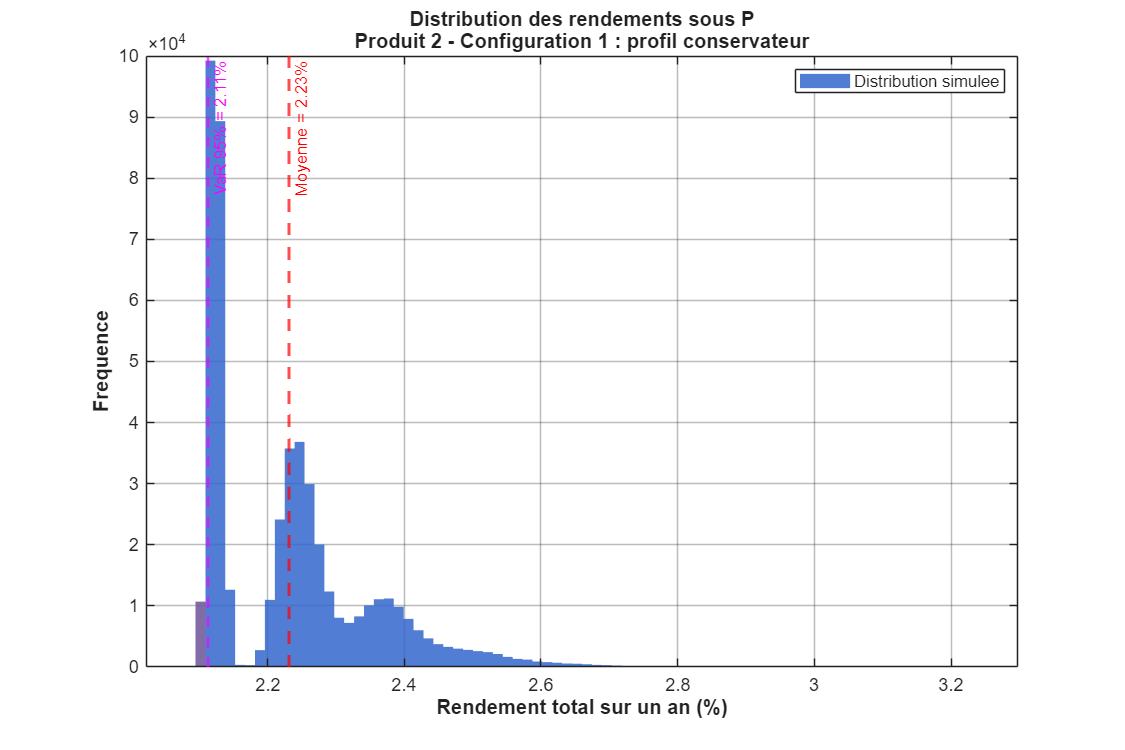

% Histogramme configuration 1

figure('Name', 'Produit 2 - Configuration conservatrice sous P', ...
       'Position', [100, 100, 900, 600]);

mu_1 = mean(rendement_1_P);

h1 = histogram(rendement_1_P, 80, ...
    'FaceColor', [0.2 0.4 0.8], ...
    'EdgeColor', 'none', ...
    'FaceAlpha', 0.85);
hold on;

binEdges_1   = h1.BinEdges;
binCounts_1  = h1.Values;
binCenters_1 = (binEdges_1(1:end-1) + binEdges_1(2:end)) / 2;
maskVaR_1    = binCenters_1 <= VaR_95_1;

bar(binCenters_1(maskVaR_1), binCounts_1(maskVaR_1), ...
    1.0, ...
    'FaceColor', [0.85 0.3 0.3], ...
    'FaceAlpha', 0.35, ...
    'EdgeColor', 'none');

xline(mu_1, '--r', ...
    ['Moyenne = ' num2str(mu_1, '%.2f') '%'], ...
    'LineWidth', 1.8);

xline(VaR_95_1, '--m', ...
    ['VaR 95% = ' num2str(VaR_95_1, '%.2f') '%'], ...
    'LineWidth', 1.5);

xlabel('Rendement total sur un an (%)', ...
    'FontSize', 12, 'FontWeight', 'bold');
ylabel('Frequence', ...
    'FontSize', 12, 'FontWeight', 'bold');

title({'Distribution des rendements sous P', ...
       'Produit 2 - Configuration 1 : profil conservateur'}, ...
      'FontSize', 14, ...
      'FontWeight', 'bold', ...
      'Interpreter', 'none');

legend(h1, 'Distribution simulee', ...
    'Location', 'northeast', ...
    'FontSize', 10);

grid on;
box on;

ax = gca;
ax.FontSize = 11;
ax.GridAlpha = 0.3;

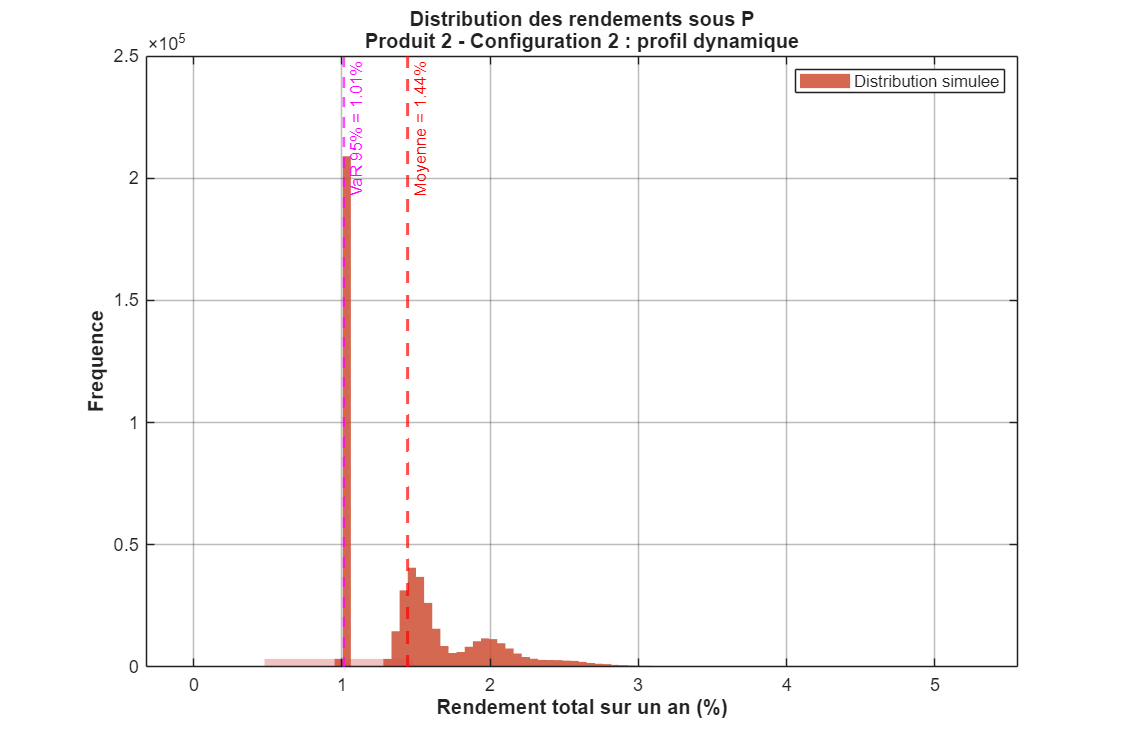

% Histogramme configuration 2

figure('Name', 'Produit 2 - Configuration dynamique sous P', ...
       'Position', [150, 150, 900, 600]);

mu_2 = mean(rendement_2_P);

h2 = histogram(rendement_2_P, 80, ...
    'FaceColor', [0.8 0.3 0.2], ...
    'EdgeColor', 'none', ...
    'FaceAlpha', 0.85);
hold on;

binEdges_2   = h2.BinEdges;
binCounts_2  = h2.Values;
binCenters_2 = (binEdges_2(1:end-1) + binEdges_2(2:end)) / 2;
maskVaR_2    = binCenters_2 <= VaR_95_2;

bar(binCenters_2(maskVaR_2), binCounts_2(maskVaR_2), ...
    1.0, ...
    'FaceColor', [0.85 0.3 0.3], ...
    'FaceAlpha', 0.35, ...
    'EdgeColor', 'none');

xline(mu_2, '--r', ...
    ['Moyenne = ' num2str(mu_2, '%.2f') '%'], ...
    'LineWidth', 1.8);

xline(VaR_95_2, '--m', ...
    ['VaR 95% = ' num2str(VaR_95_2, '%.2f') '%'], ...
    'LineWidth', 1.5);

xlabel('Rendement total sur un an (%)', ...
    'FontSize', 12, 'FontWeight', 'bold');
ylabel('Frequence', ...
    'FontSize', 12, 'FontWeight', 'bold');

title({'Distribution des rendements sous P', ...
       'Produit 2 - Configuration 2 : profil dynamique'}, ...
      'FontSize', 14, ...
      'FontWeight', 'bold', ...
      'Interpreter', 'none');

legend(h2, 'Distribution simulee', ...
    'Location', 'northeast', ...
    'FontSize', 10);

grid on;
box on;

ax = gca;
ax.FontSize = 11;
ax.GridAlpha = 0.3;

function [S, V, RV] = simulate_heston_P(S0, v0, kappa, theta, xi, rho, mu_P, dt, n, N, temps_obs)


    M = length(temps_obs);

    S = zeros(n+1, N);
    V = zeros(n+1, N);

    S(1,:) = S0;
    V(1,:) = v0;

    L = [1, 0; rho, sqrt(1 - rho^2)];

    for t = 1:n
        Z      = randn(2, N);
        Z_corr = L * Z;

        dWs = sqrt(dt) * Z_corr(1,:);
        dWv = sqrt(dt) * Z_corr(2,:);

        Vt = max(V(t,:), 0);

        V(t+1,:) = max(V(t,:) + kappa*(theta - Vt)*dt + xi*sqrt(Vt).*dWv, 0);

        S(t+1,:) = S(t,:) .* exp((mu_P - 0.5*Vt)*dt + sqrt(Vt).*dWs);
    end

    Rets = log(S(2:end,:) ./ S(1:end-1,:));

    RV = zeros(M, N);
    idx_prev = 0;

    for k = 1:M
        idx_k  = temps_obs(k);
        rets_k = Rets(idx_prev+1:idx_k, :);
        nk     = size(rets_k, 1);

        RV(k,:) = sqrt(252 / nk * sum(rets_k.^2, 1));

        idx_prev = idx_k;
    end
end